Matlab code for the Course: **Modelling and Simulation Mechatronics System**

by Enrico Bertolazzi and Francesco Biral

Dipartimento di Ingegneria Industriale

Università degli Studi di Trento

email: [enrico.bertolazzi@unitn.it](mailto:enrico.bertolazzi@unitn.it)

### Initialize by cleaning memory and widows

clc;
clear all;
close all;

#### Initialize parameters of the model and instantiate model class

data.gravity = 9.81;
data.L1      = 1;
data.L2      = 1;
data.m1      = 1;
data.m2      = 1;
eta          = 1;
omega        = 10;
ode          = DoublePendulum8EQ( data, eta, omega );

ode.setBuamgarte(eta_new, omega_new)

### Initialize 3 solver for comparison

solver_1 = Collatz();
solver_2 = RK4();
solver_3 = GaussLegendre4();

LEGEND = {'Collatz', 'RK4','GaussLegendre4'};

solver_1.setODE(ode);
solver_2.setODE(ode);
solver_3.setODE(ode);

### Set time step and inital conditions for solvers

DT = 0.025;
T  = 10;
theta1 = pi/2;
theta2 = pi/2;
x1 = data.L1*sin(theta1);
y1 = data.L1*cos(theta1);
x2 = x1+data.L2*sin(theta2);
y2 = y1+data.L2*cos(theta2);
u1 = 0;
v1 = 0;
u2 = 0;
v2 = 0;
ini = [ x1, y1, x2, y2, u1, v1, u2, v2 ];
tt = 0:DT:T;

### Compute solutions

sol_1 = solver_1.advance( tt, ini, false, true, 100 );

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
 75%
 80%
 85%
 90%
 95%
100%


sol_2 = solver_2.advance( tt, ini, false, true, 100 );

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
 75%
 80%
 85%
 90%
 95%
100%


sol_3  = solver_3.advance( tt, ini, false, true, 100 );

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
 75%
 80%
 85%
 90%
 95%
100%


### Extract computed solution

x_1  = sol_1(1,:);
y_1  = sol_1(2,:);
xx_1 = sol_1(3,:);
yy_1 = sol_1(4,:);

x_2  = sol_2(1,:);
y_2  = sol_2(2,:);
xx_2 = sol_2(3,:);
yy_2 = sol_2(4,:);

x_3  = sol_3(1,:);
y_3  = sol_3(2,:);
xx_3 = sol_3(3,:);
yy_3 = sol_3(4,:);

### Plot computed solution

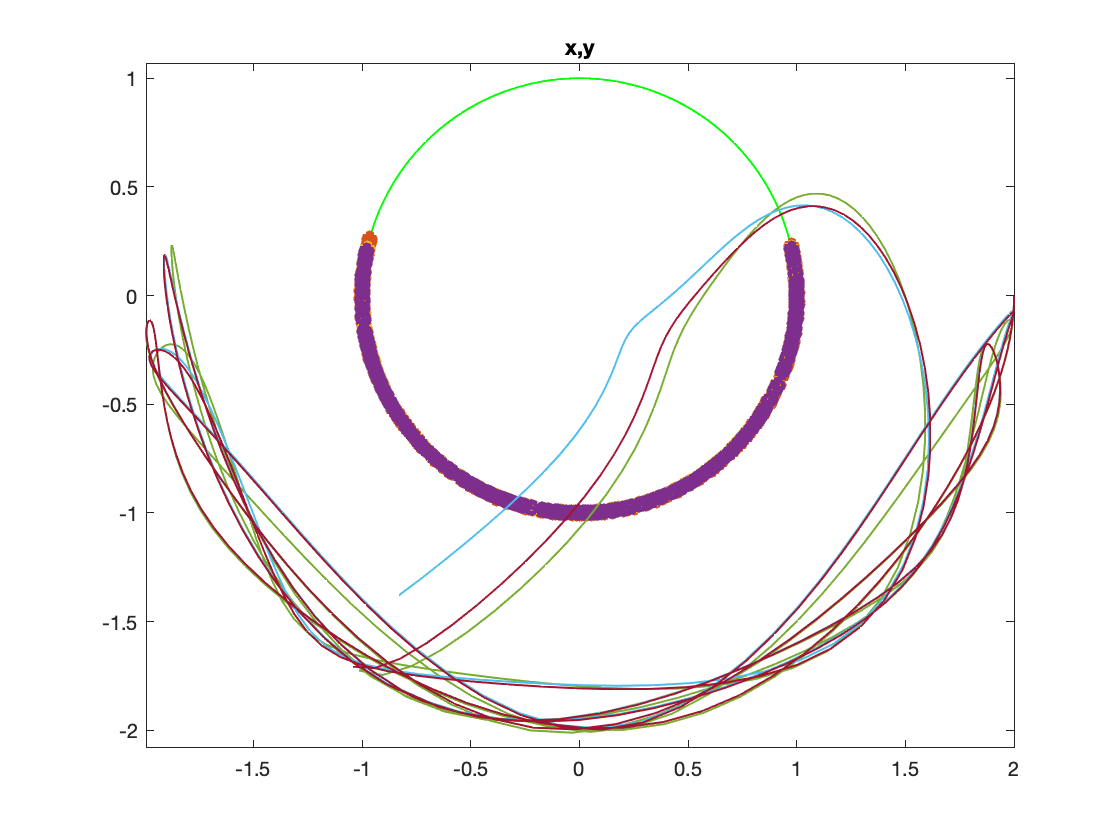

h = figure();
a = 0:0.01:2*pi;
plot( data.L1*cos(a), data.L1*sin(a), '-', 'Linewidth', 1, 'Color','green' );
hold on;
% get mass position

axis equal
plot( x_1, y_1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_2, y_2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_3, y_3, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( xx_1, yy_1, '-', 'Linewidth', 1 );
plot( xx_2, yy_2, '-', 'Linewidth', 1 );
plot( xx_3, yy_3, '-', 'Linewidth', 1 );
title('x,y');

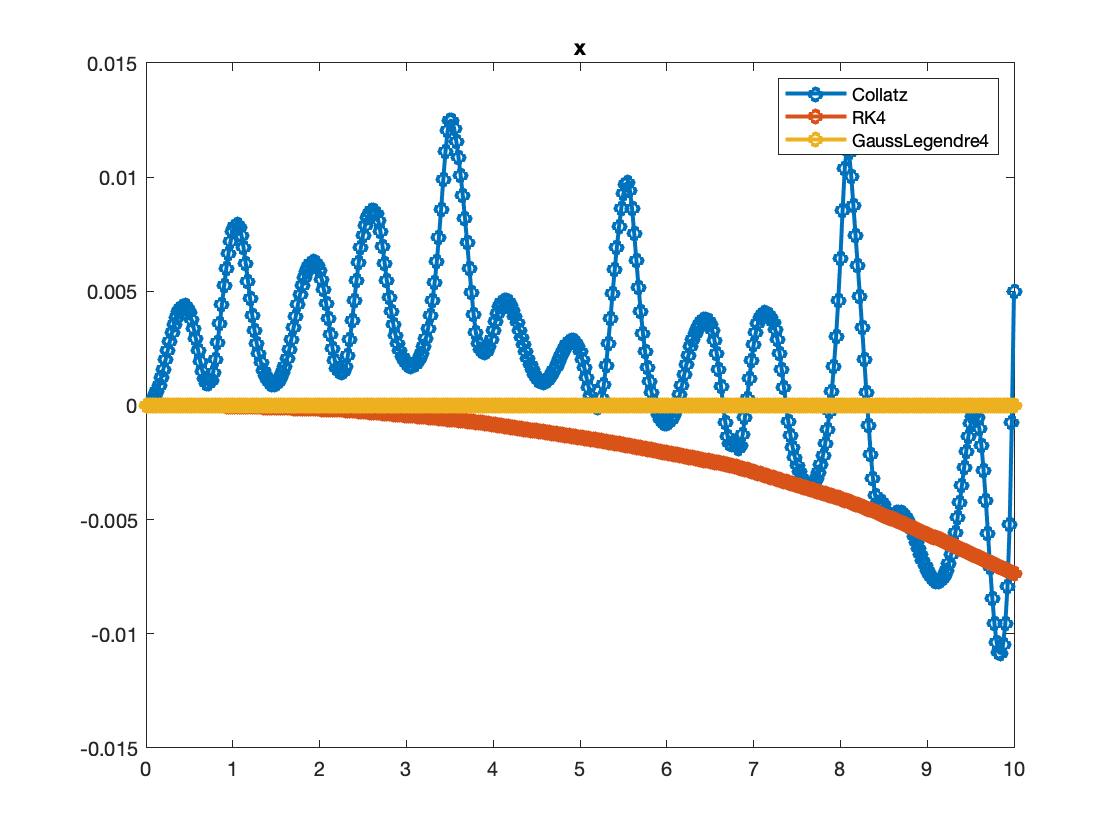

h = figure();
plot( tt, x_1.^2+y_1.^2-data.L1^1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
hold on;
plot( tt, x_2.^2+y_2.^2-data.L1^1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( tt, x_3.^2+y_3.^2-data.L1^1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
legend(LEGEND);
title('x');

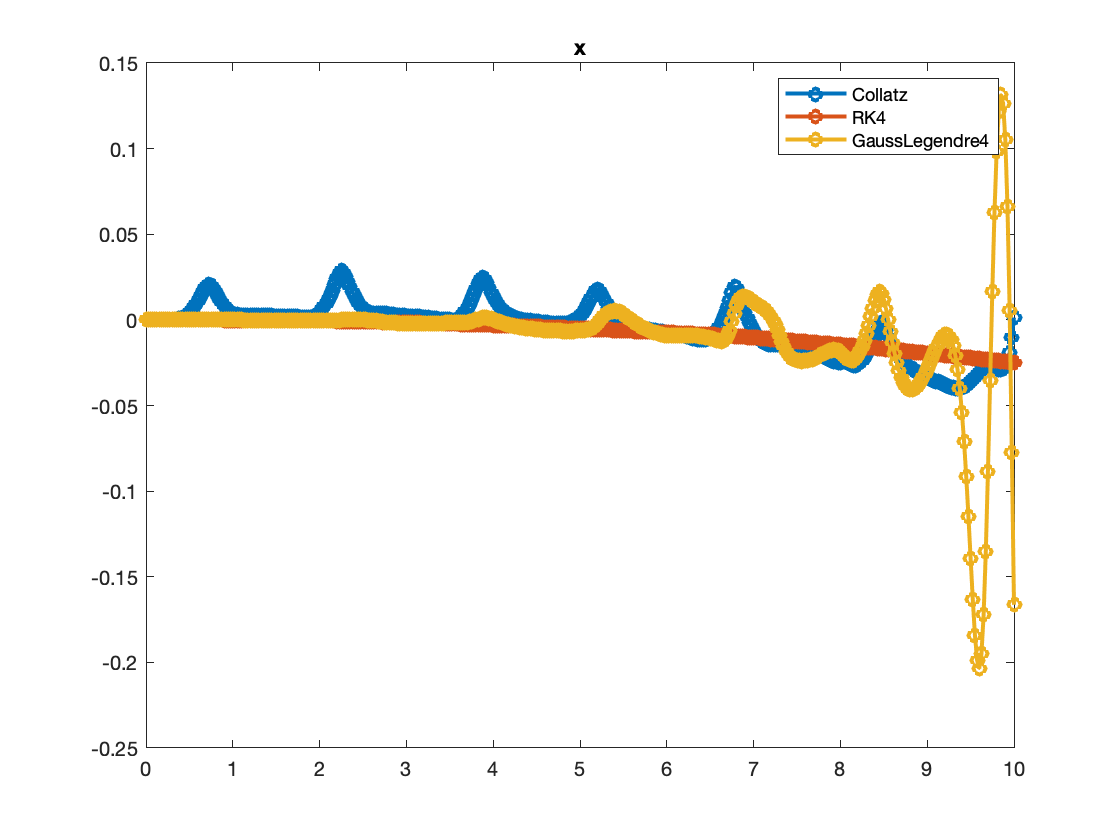

h = figure();
plot( tt, (x_1-xx_1).^2+(y_1-yy_1).^2-data.L2^1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
hold on;
plot( tt, (x_2-xx_2).^2+(y_2-yy_2).^2-data.L2^1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( tt, (x_3-xx_2).^2+(y_3-yy_3).^2-data.L2^1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
legend(LEGEND);
title('x');

### Make animation of the solution

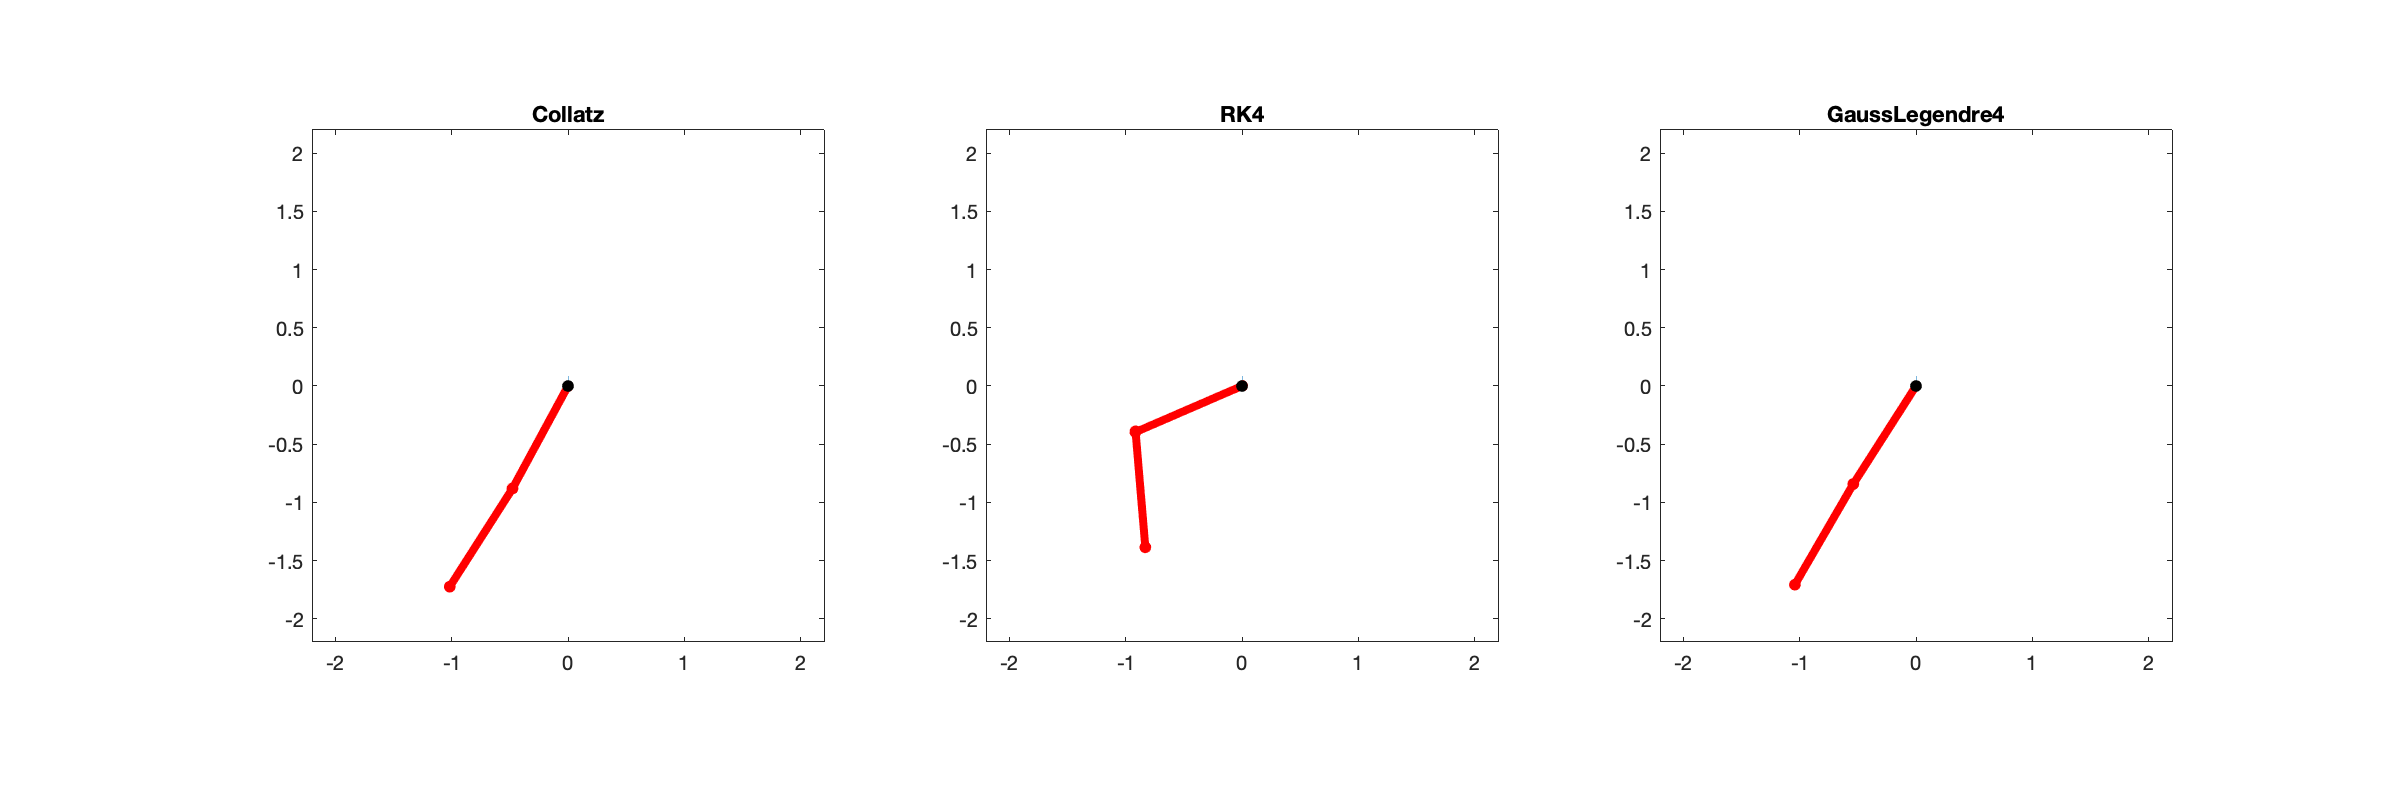

if true
  figure('Position', [1 1 1200 400]);
  for k=1:10:length(tt)
    subplot(1,3,1);
    ode.plot( tt(k), sol_1(:,k));
    title(LEGEND{1});
    subplot(1,3,2);
    ode.plot( tt(k), sol_2(:,k));
    title(LEGEND{2});
    subplot(1,3,3);
    ode.plot( tt(k), sol_3(:,k));
    title(LEGEND{3});
    drawnow limitrate;
    pause(0.01);
  end
end

### Compute solutions activating projection

sol_1 = solver_1.advance( tt, ini, true, true );

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
 75%
 80%
 85%
 90%
 95%
100%


sol_2 = solver_2.advance( tt, ini, true, true );

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
 75%
 80%
 85%
 90%
 95%
100%


sol_3 = solver_3.advance( tt, ini, true, true );

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
 75%
 80%
 85%
 90%
 95%
100%


### Extract computed solution

x_1  = sol_1(1,:);
y_1  = sol_1(2,:);
xx_1 = sol_1(3,:);
yy_1 = sol_1(4,:);

x_2  = sol_2(1,:);
y_2  = sol_2(2,:);
xx_2 = sol_2(3,:);
yy_2 = sol_2(4,:);

x_3  = sol_3(1,:);
y_3  = sol_3(2,:);
xx_3 = sol_3(3,:);
yy_3 = sol_3(4,:);

### Plot computed solution

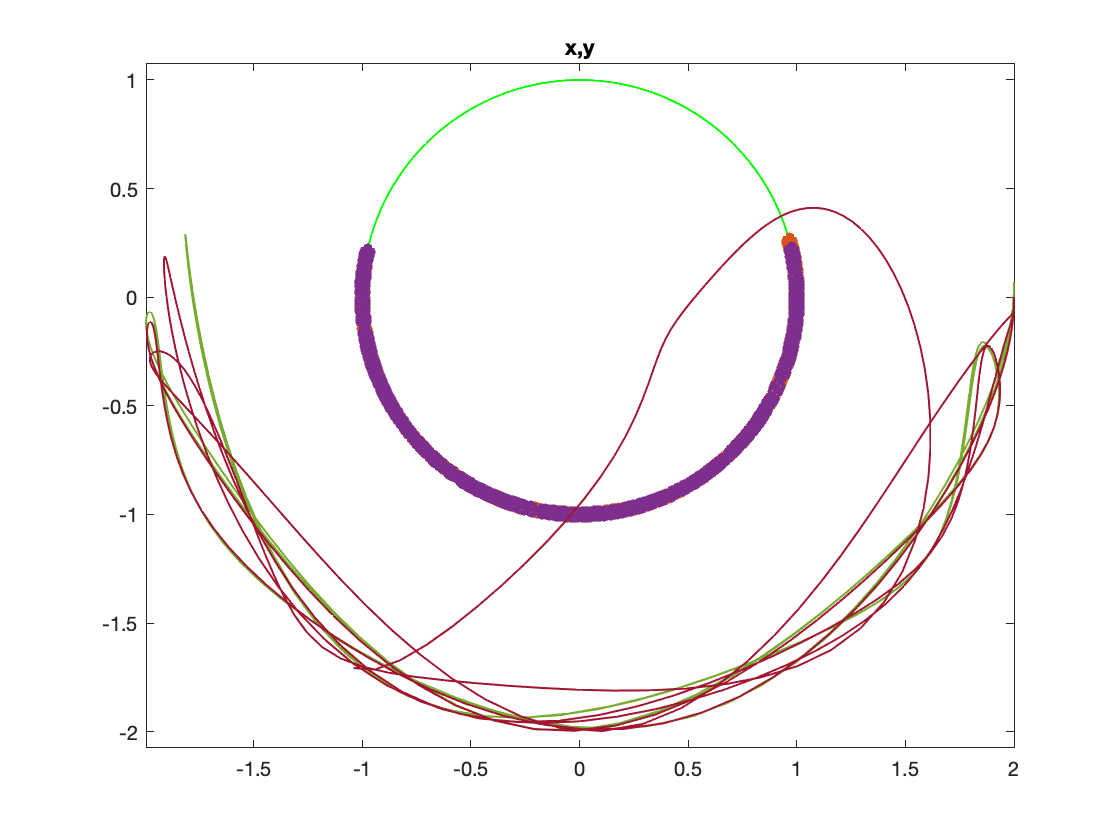

h = figure();
a = 0:0.01:2*pi;
plot( data.L1*cos(a), data.L1*sin(a), '-', 'Linewidth', 1, 'Color','green' );
hold on;
% get mass position

axis equal
plot( x_1, y_1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_2, y_2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x_3, y_3, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( xx_1, yy_1, '-', 'Linewidth', 1 );
plot( xx_2, yy_2, '-', 'Linewidth', 1 );
plot( xx_3, yy_3, '-', 'Linewidth', 1 );
title('x,y');

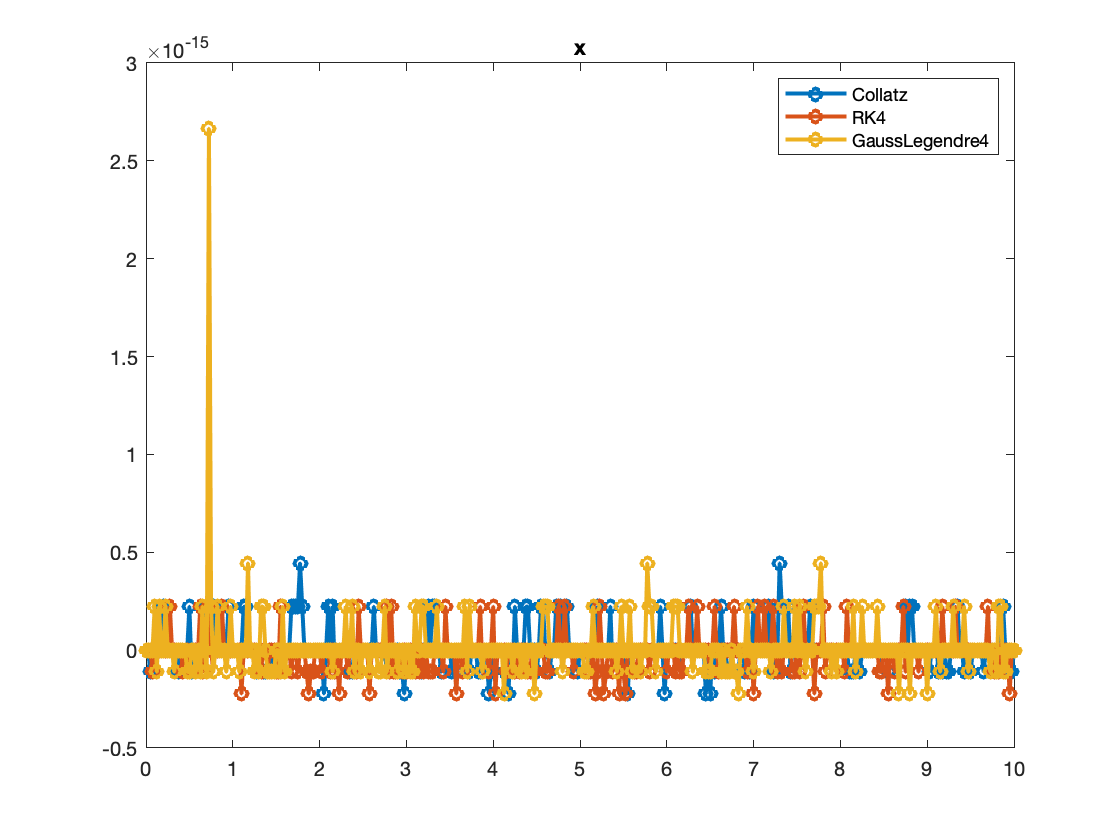

h = figure();
plot( tt, x_1.^2+y_1.^2-data.L1^1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
hold on;
plot( tt, x_2.^2+y_2.^2-data.L1^1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( tt, x_3.^2+y_3.^2-data.L1^1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
legend(LEGEND);
title('x');

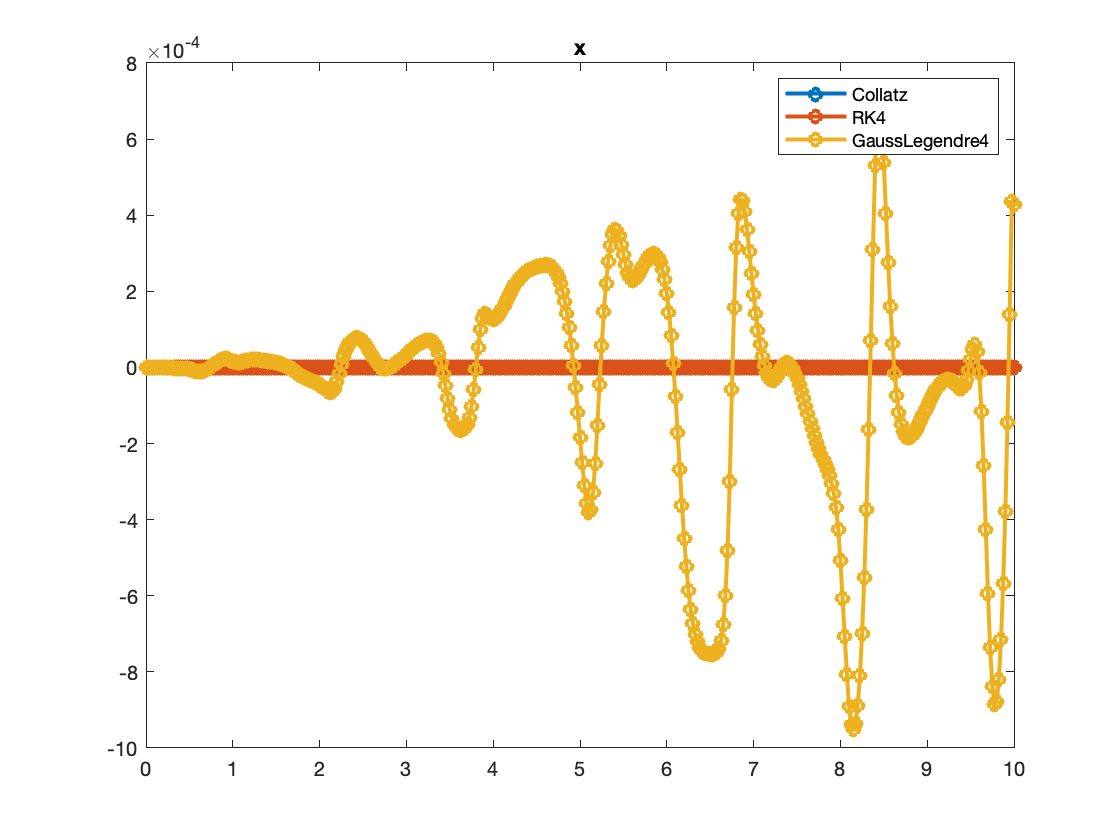

h = figure();
plot( tt, (x_1-xx_1).^2+(y_1-yy_1).^2-data.L2^1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
hold on;
plot( tt, (x_2-xx_2).^2+(y_2-yy_2).^2-data.L2^1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( tt, (x_3-xx_2).^2+(y_3-yy_3).^2-data.L2^1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
legend(LEGEND);
title('x');

### Make animation of the solution

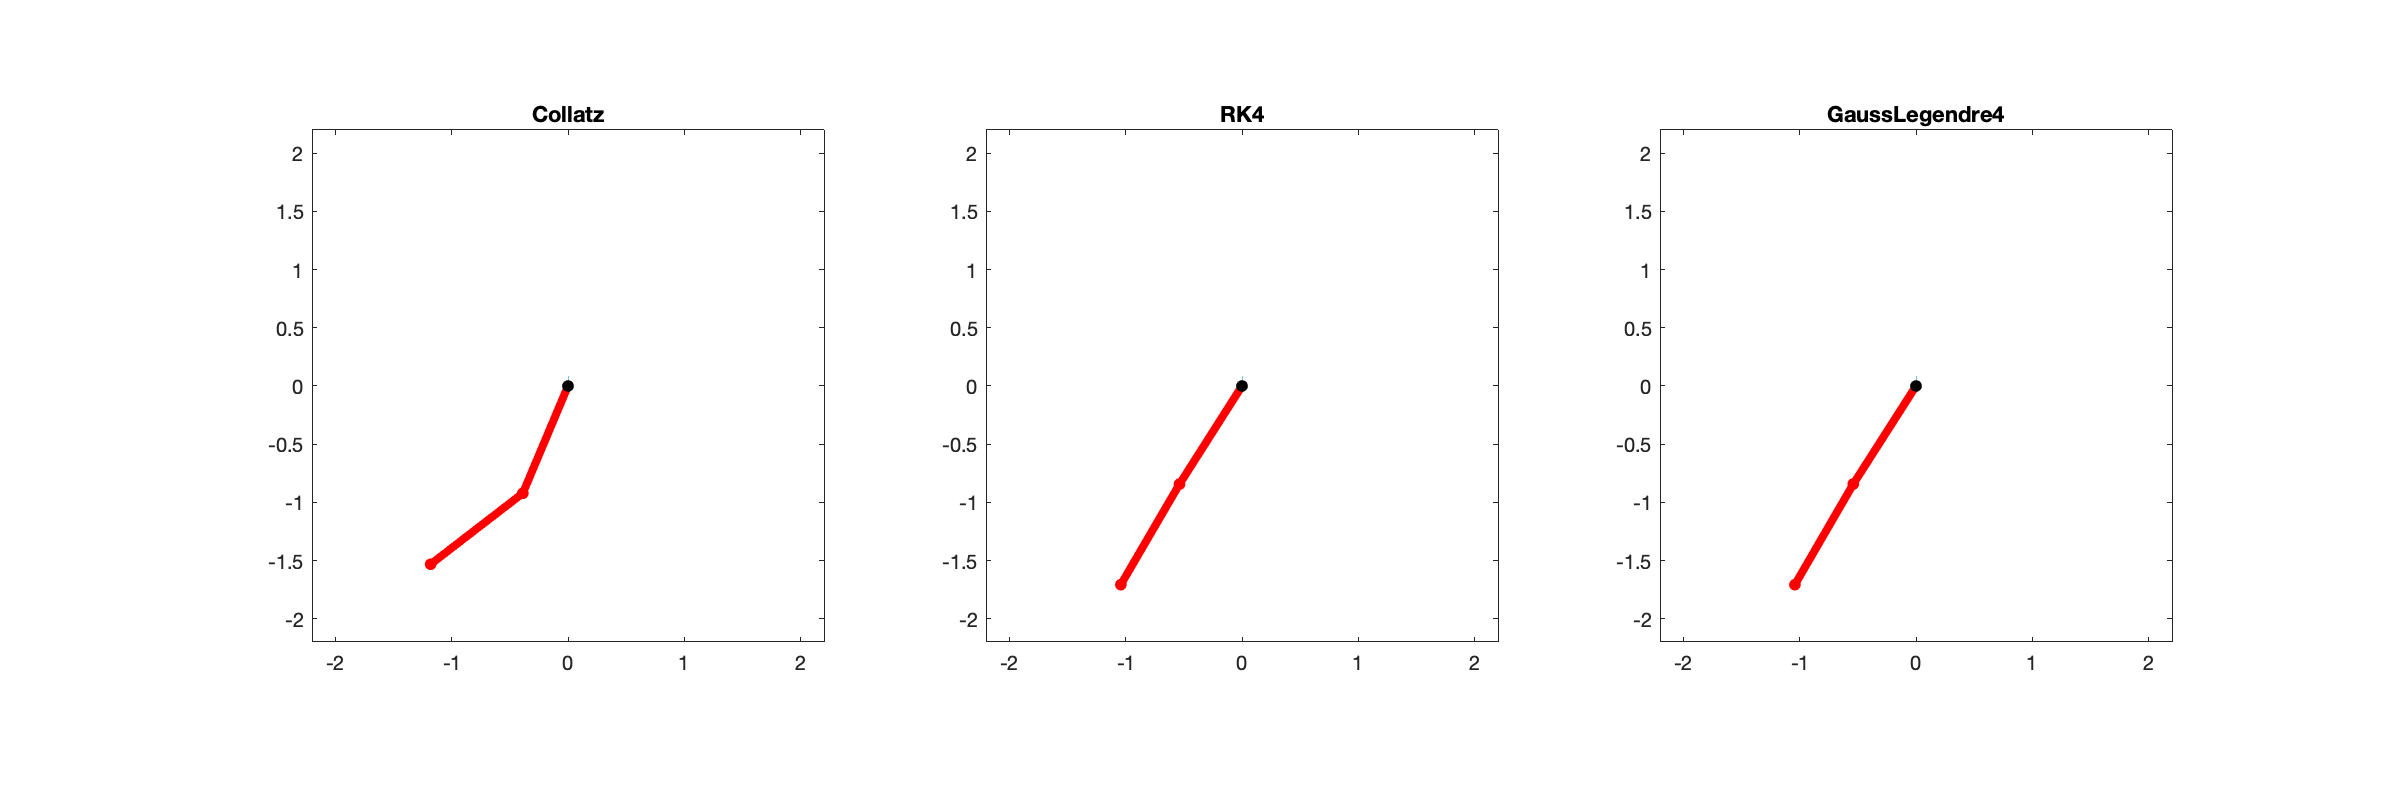

h = figure('Position',[0 0 1200 400]);
for k=1:10:length(tt)
  subplot(1,3,1);
  ode.plot( tt(k), sol_1(:,k));
  title(LEGEND{1});
  subplot(1,3,2);
  ode.plot( tt(k), sol_2(:,k));
  title(LEGEND{2});
  subplot(1,3,3);
  ode.plot( tt(k), sol_3(:,k));
  title(LEGEND{3});
  drawnow limitrate;
  pause(0.01);
end